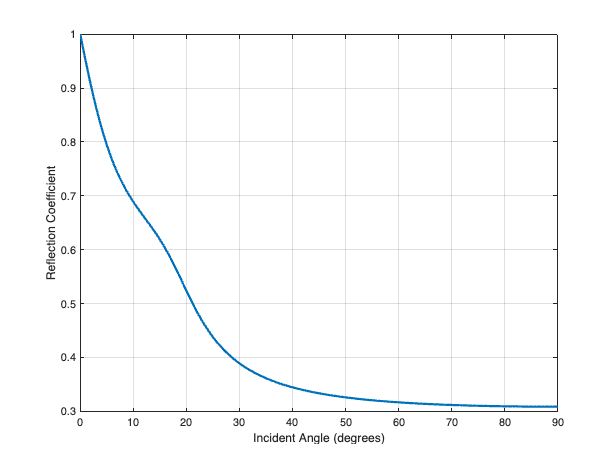

% sedType = 0;

f = 400000;

cp = 1480;
cw = 1500;
rhop = 1.4;
rhow = 1;
alphap = round(100*40*pi*f*0.01/(cp*log(10)))/100;

% 
% if sedType == 1
% 
%     cw = 1500;
%     cp = 1.15*cw;
%     rhop = 2.051;
%     rhow = 1;
%     alphap = 317.1;
% 
% 
% elseif sedType == 2
% 
%     cw = 1500;
%     cp = 0.982*cw;
%     rhop = 1.546;
%     rhow = 1;
%     alphap = 66.2;
% 
% elseif sedType == 3
% 
%     cw = 1500;
%     cp = 1.01*cw;
%     rhop = 1.597;
%     rhow = 1;
%     alphap = 190.7;
% 
% 
% end

cp1 = 1577;
rhop1 = 1.8;
alphap1 = 482;


deltap1 = alphap1*cp*log(10)/(40*pi*f);

theta_i_degrees = 0:0.5:90;
theta_i = theta_i_degrees*pi/180;

cpp = cp1./(1 + 1i*deltap1);

ap = cpp/cw; % ratio of sound speeds

zw = rhow*cw./sin(theta_i); % impedance for water

zp = rhop1*cpp./sqrt(1 - (ap*cos(theta_i)).^2); % impedance of sediment

zwp = zp./zw; % impedance ratio

vww = (zwp - 1)./(zwp + 1); % reflection coefficient

plot(theta_i_degrees,abs(vww),'linewidth',2)

a = gca;
a.XLabel.String = 'Incident Angle (degrees)';
a.YLabel.String = 'Reflection Coefficient';
grid on